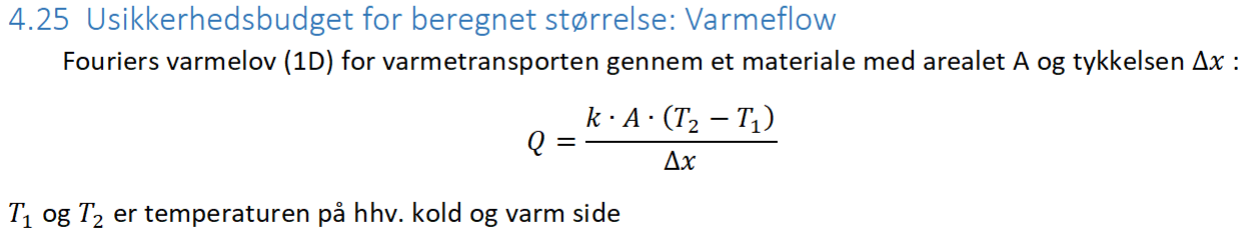

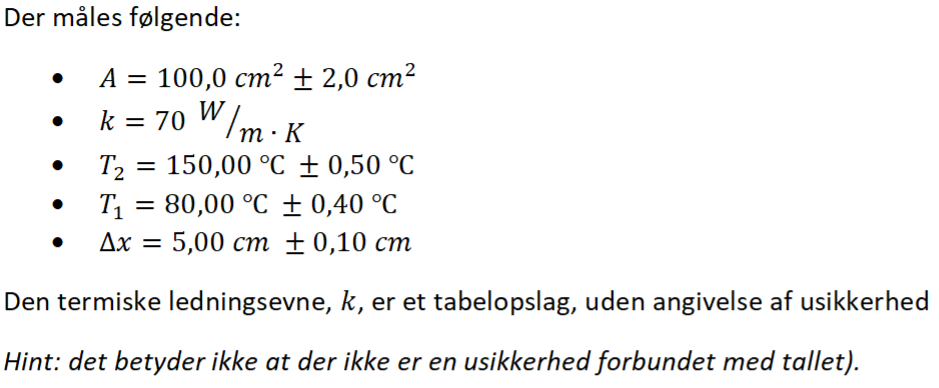

### A.

Argumenter for fordelingstype for hvert enkelt bidrag

Hint: Der er ikke nogen rigtige eller forkerte svar, men antagelse og argument skal passe sammen – forsøg at benytte alle fordelingstyper (hvis du digter lidt)?

Målingerne på vores **areal** **A** kan ses som **trekants fordelt** vi kan forstille os der er lavet to firkantfordelte målinger for at afgøre arealet.

Dette kunne være siderne $l_1$ og $l_2$ eller længde og radius af et rør.

Den **termiske ledning k** kan ses som en normalfordeling med lille spredning da den nok er lavet af mange præcise målinger af et labratorie. Vi ser her på den som havende en spredning på afrundingen således $\pm 0,49$.

**Temperatur målingerne **$T_1$  og $T_2$ kunne være **firkant fordelt** hvis man ser dem som digitale termometre der har en indbyggede fejl der tilfældigt lægger et tal $\pm u$ til målingen

Vi ser  $\Delta x$ som **U fordelt** da vi kan have en lille markering på målepinden der hvor den præcise måling er, hvilket besværliggøre en fuldstændig præcis måling.

### B.

Beregn standardusikkerheden under ovenstående antagelser?

Bemærk: Bemærk at resultatet afhænger af dine valg i A, så forskellige resultater kan være rigtige

clear
A_val = 100 /100 / 100; % m^2
a_A = 2 / 100 / 100;
u_A = a_A/sqrt(6) %trekant fordelt

u_A = 8.1650e-05

k_val = 70; % W/(m*K)
a_k = 0.99;
u_k = 0.49 % nok mere præcist normalt fordelt med en udregnede spredning eller man burde finde de korrekt usikkerheder på tabel værdierne

u_k = 0.4900

T_1_val = 80 + 273.15; % K
a_T_1 = 0.40;
u_T_1 = a_T_1/sqrt(3) %firkant fordelt

u_T_1 = 0.2309

T_2_val = 150 + 273.15; % K
a_T_2 = 0.50;
u_T_2 = a_T_2/sqrt(3) %firkantfordelt

u_T_2 = 0.2887

Delta_x_val = 5 /100 ; % m
a_Delta_x = 0.10 /100;
u_Delta_x = a_Delta_x/sqrt(3) %U fordelt

u_Delta_x = 5.7735e-04

### C.

Lav usikkerhedsberegningen så du bestemmer u(Q)

Vi udregner først resultatet af funktionen

Q = k_val * A_val * (T_2_val - T_1_val) / Delta_x_val

Q = 980.0000

Vi kan nu benytte ophobningsloven til at udregne usikkerheden på vores resultat.

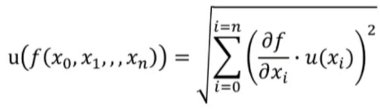

Vi tager således for hver af vores input med udsikkerheder den partielt afledte og ganger den med usikkerheden for dette input og kvadrer.

Alle led summes og der tages kvadrat roden. 

syms A k T_1 T_2 Delta_x
Q_sym = k * A * (T_2 - T_1) / Delta_x;
vars_and_u = [[A, A_val, u_A]; 
              [k, k_val, u_k];
              [T_1, T_1_val, u_T_1];
              [T_2, T_2_val, u_T_2];
              [Delta_x, Delta_x_val, u_Delta_x]
              ];
% vars_and_u(:,1), vars_and_u(:,2), vars_and_u(:,3)
[y, y_u] = STAT.Ophobningsloven_m(Q_sym, vars_and_u)

980.0±16.31

y = 980

y_u = 16.3072

Det ses således at Vi får $Q=980\pm16,3\ W$

Her er **STAT.Ophobningsloven_m funktionen** skrevet til at benytte ophobningsloven generelt.